% Params:
syms ma mr la lr m1 m2 m3 m4 m5 m6 ;
syms L1 L2 L3 L4 L5 L6 ;
syms ra rr g;

% angulos
syms q1(t) q2(t) q3(t) q4(t) q5(t) q6(t)
q1_d(t) = diff(q1(t));
q2_d(t) = diff(q2(t));
q3_d(t) = diff(q3(t));
q4_d(t) = diff(q4(t));
q5_d(t) = diff(q5(t));
q6_d(t) = diff(q6(t));


% Coordenadas

x1 = 0;
y1 = 0;
z1 = (ma*la + mr*lr)/(ma + mr);

x2 = L2/2 * sin(q2(t))*cos(q1(t));
y2 = L2/2 * sin(q2(t))*sin(q1(t));
z2 = L1 + L2/2*cos(q2(t));

x3 = ( L2 * sin(q2(t)) + L3/2 * sin(q3(t)) ) * cos(q1(t));
y3 = ( L2 * sin(q2(t)) + L3/2 * sin(q3(t)) ) * sin(q1(t));
z3 = L1 + L2/2 * cos(q2(t)) + L3/2 * cos(q3(t));

x4 = x3 + L3/2 * sin(q3(t)) * cos(q1(t)) + ( L4/2 * sin(q4(t)) * cos(q1(t)) );
y4 = y3 + L3/2 * sin(q3(t)) * sin(q1(t)) + ( L4/2 * sin(q4(t)) * sin(q1(t)) );
z4 = z3 + L3/2 * cos(q3(t)) + L4/2 * cos(q4(t));

x5 = x4 + L4/2 * sin(q4(t)) * cos(q1(t)) + ( L5/2 * sin(q5(t)) * cos(q1(t)) );
y5 = y4 + L4/2 * sin(q4(t)) * sin(q1(t)) + ( L5/2 * sin(q5(t)) * sin(q1(t)) );
z5 = z4 + L4/2 * cos(q4(t)) + L5/2 * cos(q5(t));

x6 = x5 + L5/2 * sin(q5(t)) * cos(q1(t)) + ( L6/2 * sin(q6(t)) * cos(q1(t)) );
y6 = y5 + L5/2 * sin(q5(t)) * sin(q1(t)) + ( L6/2 * sin(q6(t)) * sin(q1(t)) );
z6 = z5 + L5/2 * cos(q5(t)) + L6/2 * cos(q6(t));

x2_d = diff(x2);
y2_d = diff(y2);
z2_d = diff(z2);

x3_d = diff(x3);
y3_d = diff(y3);
z3_d = diff(z3);

x4_d = diff(x4);
y4_d = diff(y4);
z4_d = diff(z4);

x5_d = diff(x5);
y5_d = diff(y5);
z5_d = diff(z5);

x6_d = diff(x6);
y6_d = diff(y6);
z6_d = diff(z6);

% Momentos de inercia: 



% Energías: 
syms J1 J2 J3 J4 J5 J6
V1 = 1/2*J1*q1_d(t)^2;
U1 = m1*g*(ma*la + mr*lr)/(ma + mr);

V2 = 1/2*J2*q2_d(t)^2 + 1/2*m2*(x2_d^2 + y2_d^2 + z2_d^2);
U2 = m2*g*(L1 + L2/2*cos(q2(t)));

V3 = 1/2*J3*q3_d(t)^2 + 1/2*m3*(x3_d^2 + y3_d^2 + z3_d^2);
U3 = m3*g*z3;

V4 = 1/2*J4*q4_d(t)^2 + 1/2*m4*(x4_d^2 + y4_d^2 + z4_d^2);
U4 = m4*g*z4;

V5 = 1/2*J5*q5_d(t)^2 + 1/2*m5*(x5_d^2 + y5_d^2 + z5_d^2);
U5 = m5*g*z5;

V6 = 1/2*J6*q6_d(t)^2 + 1/2*m6*(x6_d^2 + y6_d^2 + z6_d^2);
U6 = m6*g*z6;

#### Formula de Laplace y Derivadas

V = V1 + V2 + V3 + V4 + V5 + V6;
U = U1 + U2 + U3 + U4 + U5 + U6;
L = simplify(expand(V - U));
clear V1 V2 V3 V4 V5 V6 U1 U2 U3 U4 U5 U6

% torques listos:

t1 = diff(diff(L,q1_d(t))) - diff(L, q1(t));
t2 = diff(diff(L,q2_d(t))) - diff(L, q2(t));
t3 = diff(diff(L,q3_d(t))) - diff(L, q3(t));
t4 = diff(diff(L,q4_d(t))) - diff(L, q4(t));
t5 = diff(diff(L,q5_d(t))) - diff(L, q5(t));
t6 = diff(diff(L,q6_d(t))) - diff(L, q6(t));

Ahora, reemplazando las relaciones del voltaje de entrada y los torques:

% constantes de los motores:
syms Jg Jm Bm Bg Km Kb Ka Ra
n = 1.3  %relacion de engranajes

n = 1.3000


% Better with sub() (replace the symbolic variable with a value)
% Km = 0.0458;
% Kb = 0.0458;
% Ka = 8.5
% Ra = 2.49

Jeq = n^2*Jm + Jg

$$Jeq = \mathrm{Jg}+\frac{169\,\mathrm{Jm}}{100}$$

Beq = n^2*Bm + Bg

$$Beq = \mathrm{Bg}+\frac{169\,\mathrm{Bm}}{100}$$

q1dd = diff(q1_d(t));
q2dd = diff(q2_d(t));
q3dd = diff(q3_d(t));
q4dd = diff(q4_d(t));
q5dd = diff(q5_d(t));
q6dd = diff(q6_d(t));

% ecuaciones que describen las entradas y salidas: (u: entradas, qs:
% salidas)
u1 = (t1 - (-Jeq*q1dd - (Beq + n^2*Km*Kb/Ra)*q1_d(t)))*Ra/(n*Km*Ka);
u2 = (t2 - (-Jeq*q2dd - (Beq + n^2*Km*Kb/Ra)*q2_d(t)))*Ra/(n*Km*Ka);
u3 = (t3 - (-Jeq*q3dd - (Beq + n^2*Km*Kb/Ra)*q3_d(t)))*Ra/(n*Km*Ka);
u4 = (t4 - (-Jeq*q4dd - (Beq + n^2*Km*Kb/Ra)*q4_d(t)))*Ra/(n*Km*Ka);
u5 = (t5 - (-Jeq*q5dd - (Beq + n^2*Km*Kb/Ra)*q5_d(t)))*Ra/(n*Km*Ka);
u6 = (t6 - (-Jeq*q6dd - (Beq + n^2*Km*Kb/Ra)*q6_d(t)))*Ra/(n*Km*Ka);

% Matriz M invertida
% M_inv = inv(M) ***[ sacar los coeficietes de cada uno y hacer una resta
% sucesiva, asi se hallará el vector "d"
u1 = simplify(expand(u1));
M11 = coeffs(collect(u1, q1dd), q1dd); u1_ = M11(1);
M11 = M11(2);
P11 = coeffs(collect(u1_, q1_d(t)), q1_d(t)); 
P11 = P11(1); 
P12 = coeffs(collect(u1_, q2_d(t)), q2_d(t)); P12 = P12(1); 
P13 = coeffs(collect(u1_, q3_d(t)), q3_d(t)); P13 = P13(1); 
P14 = coeffs(collect(u1_, q4_d(t)), q4_d(t)); P14 = P14(1); 
P15 = coeffs(collect(u1_, q5_d(t)), q5_d(t)); P15 = P15(1); 
P16 = coeffs(collect(u1_, q6_d(t)), q6_d(t)); P16 = P16(1);


M22 = coeffs(collect(u2, q2dd), q2dd); u2_ = M22(1); M22 = M22(2); M23 = coeffs(collect(u2_, q3dd), q3dd); u2_ = M23(1); M23 = M23(2); M24 = coeffs(collect(u2_, q4dd), q4dd); u2_ = M24(1); M24 = M24(2);  M25 = coeffs(collect(u2_, q5dd), q5dd); u2_ = M25(1); M25 = M25(2); M26 = coeffs(collect(u2_, q6dd), q6dd); u2_ = M26(1); M26 = M26(2); 
P21 = coeffs(collect(u2_, q1_d(t)), q1_d(t)); u2_ = P21(1); P21 = P21(2); P22 = coeffs(collect(u2_, q2_d(t)), q2_d(t)); u2_ = P22(1); P22 = P22(2); P23 = coeffs(collect(u2_, q3_d(t)), q3_d(t)); u2_ = P23(1); P23 = P23(2); P24 = coeffs(collect(u2_, q4_d(t)), q4_d(t)); u2_ = P24(1); P24 = P24(2); P25 = coeffs(collect(u2_, q5_d(t)), q5_d(t)); u2_ = P25(1); P25 = P25(2); P26 = coeffs(collect(u2_, q6_d(t)), q6_d(t)); u2_ = P26(1); P26 = P26(2); d21 = u2_;

M32 = coeffs(collect(u3, q2dd), q2dd); u3_ = M32(1); M32 = M32(2); M33 = coeffs(collect(u3_, q3dd), q3dd); u3_ = M33(1); M33 = M33(2); M34 = coeffs(collect(u3_, q4dd), q4dd); u3_ = M34(1); M34 = M34(2);  M35 = coeffs(collect(u3_, q5dd), q5dd); u3_ = M35(1); M35 = M35(2); M36 = coeffs(collect(u3_, q6dd), q6dd); u3_ = M36(1); M36 = M36(2); 
P31 = coeffs(collect(u3_, q1_d(t)), q1_d(t)); u3_ = P31(1); P31 = P31(2); P32 = coeffs(collect(u3_, q2_d(t)), q2_d(t)); u3_ = P32(1); P32 = P32(2); P33 = coeffs(collect(u3_, q3_d(t)), q3_d(t)); u3_ = P33(1); P33 = P33(2); P34 = coeffs(collect(u3_, q4_d(t)), q4_d(t)); u3_ = P34(1); P34 = P34(2); P35 = coeffs(collect(u3_, q5_d(t)), q5_d(t)); u3_ = P35(1); P35 = P35(2); P36 = coeffs(collect(u3_, q6_d(t)), q6_d(t)); u3_ = P36(1); P36 = P36(2); d31 = u3_;

M42 = coeffs(collect(u4, q2dd), q2dd); u4_ = M42(1); M42 = M42(2); M43 = coeffs(collect(u4_, q3dd), q3dd); u4_ = M43(1); M43 = M43(2); M44 = coeffs(collect(u4_, q4dd), q4dd); u4_ = M44(1); M44 = M44(2);  M45 = coeffs(collect(u4_, q5dd), q5dd); u4_ = M45(1); M45 = M45(2); M46 = coeffs(collect(u4_, q6dd), q6dd); u4_ = M46(1); M46 = M46(2); 
P41 = coeffs(collect(u4_, q1_d(t)), q1_d(t)); u4_ = P41(1); P41 = P41(2); P42 = coeffs(collect(u4_, q2_d(t)), q2_d(t)); u4_ = P42(1); P42 = P42(2); P43 = coeffs(collect(u4_, q3_d(t)), q3_d(t)); u4_ = P43(1); P43 = P43(2); P44 = coeffs(collect(u4_, q4_d(t)), q4_d(t)); u4_ = P44(1); P44 = P44(2); P45 = coeffs(collect(u4_, q5_d(t)), q5_d(t)); u4_ = P45(1); P45 = P45(2); P46 = coeffs(collect(u4_, q6_d(t)), q6_d(t)); u4_ = P46(1); P46 = P46(2); d41 = u4_;

M52 = coeffs(collect(u5, q2dd), q2dd); u5_ = M52(1); M52 = M52(2); M53 = coeffs(collect(u5_, q3dd), q3dd); u5_ = M53(1); M53 = M53(2); M54 = coeffs(collect(u5_, q4dd), q4dd); u5_ = M54(1); M54 = M54(2);  M55 = coeffs(collect(u5_, q5dd), q5dd); u5_ = M55(1); M55 = M55(2); M56 = coeffs(collect(u5_, q6dd), q6dd); u5_ = M56(1); M56 = M56(2); 
P51 = coeffs(collect(u5_, q1_d(t)), q1_d(t)); u5_ = P51(1); P51 = P51(2); P52 = coeffs(collect(u5_, q2_d(t)), q2_d(t)); u5_ = P52(1); P52 = P52(2); P53 = coeffs(collect(u5_, q3_d(t)), q3_d(t)); u5_ = P53(1); P53 = P53(2); P54 = coeffs(collect(u5_, q4_d(t)), q4_d(t)); u5_ = P54(1); P54 = P54(2); P55 = coeffs(collect(u5_, q5_d(t)), q5_d(t)); u5_ = P55(1); P55 = P55(2); P56 = coeffs(collect(u5_, q6_d(t)), q6_d(t)); u5_ = P56(1); P56 = P56(2); d51 = u5_;

M62 = coeffs(collect(u6, q2dd), q2dd); u6_ = M62(1); M62 = M62(2); M63 = coeffs(collect(u6_, q3dd), q3dd); u6_ = M63(1); M63 = M63(2); M64 = coeffs(collect(u6_, q4dd), q4dd); u6_ = M64(1); M64 = M64(2);  M65 = coeffs(collect(u6_, q5dd), q5dd); u6_ = M65(1); M65 = M65(2); M66 = coeffs(collect(u6_, q6dd), q6dd); u6_ = M66(1); M66 = M66(2); 
P61 = coeffs(collect(u6_, q1_d(t)), q1_d(t)); u6_ = P61(1); P61 = P61(2); P62 = coeffs(collect(u6_, q2_d(t)), q2_d(t)); u6_ = P62(1); P62 = P62(2); P63 = coeffs(collect(u6_, q3_d(t)), q3_d(t)); u6_ = P63(1); P63 = P63(2); P64 = coeffs(collect(u6_, q4_d(t)), q4_d(t)); u6_ = P64(1); P64 = P64(2); P65 = coeffs(collect(u6_, q5_d(t)), q5_d(t)); u6_ = P65(1); P65 = P65(2); P66 = coeffs(collect(u6_, q6_d(t)), q6_d(t)); u6_ = P66(1); P66 = P66(2); d61 = u6_;

Reemplazando:

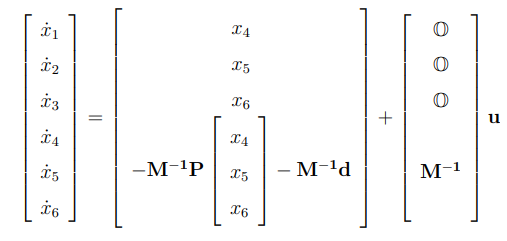

% Matriz M:
M = [M11 0 0 0 0 0;
    0 M22 M23 M24 M25 M26;
    0 M32 M33 M34 M35 M36;
    0 M42 M43 M44 M45 M46;
    0 M52 M53 M54 M55 M56;
    0 M62 M63 M64 M65 M66;];


% Patriz P:
P = [P11 P12 P13 P14 P15 P16;
    P21 P22 P23 P24 P25 P26;
    P22 P32 P33 P34 P35 P36;
    P23 P42 P43 P44 P45 P46;
    P24 P52 P53 P54 P55 P56;
    P25 P62 P63 P64 P65 P66;];

% Vector D:
D = [0; d21; d31; d41; d51; d61];

M(6x6)

P(6x6) [matriz de permutacion]

d(6x1) son las qx

De aquí cada uno realiza su controlador 

## Controlador Backstepping:

Cosas que se cambiaron:

6 dimensiones:

    q

    error de seguimiento

    observador.

    señales de referencia

Reepalzar sibolicos

% {not run} 
% Params:
% syms ma mr la lr m1 m2 m3 m4 m5 m6 
% syms L1 L2 L3 L4 L5 L6 
% syms ra rr g
% syms J1 J2 J3 J4 J5 J6
% 
% syms Jg Jm Bm Bg Km Kb Ka Ra 
M = subs(M, ma, 1.5);
M = subs(M, mr, 1.48);

M = subs(M, la, 0.3378);
M = subs(M, lr, 0.054);

M = subs(M, m1, 2.9);
M = subs(M, m2, 0.89);
M = subs(M, m3, 0.25);
M = subs(M, m4, 0.89);
M = subs(M, m5, 0.25);
M = subs(M, m6, 0.80);

M = subs(M, L1, 0.391);
M = subs(M, L2, 0.24);
M = subs(M, L3, 0.245);
M = subs(M, L4, 0.24);
M = subs(M, L5, 0.243);
M = subs(M, L6, 0.24);

M = subs(M, ra, 0.015);
M = subs(M, rr, 0.0427);
M = subs(M, g, 9.81);

M = subs(M, Jg, 0.053);
M = subs(M, Jm, 7.1e-6);
M = subs(M, Bm, 0.0001);
M = subs(M, Bg, 0.01);
M = subs(M, Km, 0.0458);
M = subs(M, Ka, 8.5);
M = subs(M, Ra, 2.49);

J1_ = 1/2*1.5*0.015^2 + 1/2*1.48*0.0427^2;
J2_ = 1/3*0.89*0.24^2;
J3_ = 1/3*0.25*0.245^2;
J4_ = 1/3*0.89*0.24^2;
J5_ = 1/3*0.25*0.243^2;
J6_ = 1/3*0.80*0.24^2;

M = subs(M, J1, J1_);
M = subs(M, J2, J2_);
M = subs(M, J3, J3_);
M = subs(M, J4, J4_);
M = subs(M, J5, J5_);
M = subs(M, J6, J6_);

M = subs(M, Kb, 0.0458);

% P matrix: 
P = subs(P, ma, 1.5);
P = subs(P, mr, 1.48);

P = subs(P, la, 0.3378);
P = subs(P, lr, 0.054);

P = subs(P, m1, 2.9);
P = subs(P, m2, 0.89);
P = subs(P, m3, 0.25);
P = subs(P, m4, 0.89);
P = subs(P, m5, 0.25);
P = subs(P, m6, 0.80);

P = subs(P, L1, 0.391);
P = subs(P, L2, 0.24);
P = subs(P, L3, 0.245);
P = subs(P, L4, 0.24);
P = subs(P, L5, 0.243);
P = subs(P, L6, 0.24);

P = subs(P, ra, 0.015);
P = subs(P, rr, 0.0427);
P = subs(P, g, 9.81);

P = subs(P, Jg, 0.053);
P = subs(P, Jm, 7.1e-6);
P = subs(P, Bm, 0.0001);
P = subs(P, Bg, 0.01);
P = subs(P, Km, 0.0458);
P = subs(P, Ka, 8.5);
P = subs(P, Ra, 2.49);

P = subs(P, J1, J1_);
P = subs(P, J2, J2_);
P = subs(P, J3, J3_);
P = subs(P, J4, J4_);
P = subs(P, J5, J5_);
P = subs(P, J6, J6_);

P = subs(P, Kb, 0.0458);
simplify(expand(P))


% d vector:
D = subs(D, ma, 1.5);
D = subs(D, mr, 1.48);

D = subs(D, la, 0.3378);
D = subs(D, lr, 0.054);

D = subs(D, m1, 2.9);
D = subs(D, m2, 0.89);
D = subs(D, m3, 0.25);
D = subs(D, m4, 0.89);
D = subs(D, m5, 0.25);
D = subs(D, m6, 0.80);

D = subs(D, L1, 0.391);
D = subs(D, L2, 0.24);
D = subs(D, L3, 0.245);
D = subs(D, L4, 0.24);
D = subs(D, L5, 0.243);
D = subs(D, L6, 0.24);

D = subs(D, ra, 0.015);
D = subs(D, rr, 0.0427);
D = subs(D, g, 9.81);

D = subs(D, Jg, 0.053);
D = subs(D, Jm, 7.1e-6);
D = subs(D, Bm, 0.0001);
D = subs(D, Bg, 0.01);
D = subs(D, Km, 0.0458);
D = subs(D, Ka, 8.5);
D = subs(D, Ra, 2.49);

D = subs(D, J1, J1_);
D = subs(D, J2, J2_);
D = subs(D, J3, J3_);
D = subs(D, J4, J4_);
D = subs(D, J5, J5_);
D = subs(D, J6, J6_);

syms q1_ q2_ q3_ q4_ q5_ q6_

M = subs(M, q1(t), q1_);
M = subs(M, q2(t), q2_);
M = subs(M, q3(t), q3_);
M = subs(M, q4(t), q4_);
M = subs(M, q5(t), q5_);
M = subs(M, q6(t), q6_)


P = subs(P, q1(t), q1_);
P = subs(P, q2(t), q2_);
P = subs(P, q3(t), q3_);
P = subs(P, q4(t), q4_);
P = subs(P, q5(t), q5_);
P = subs(P, q6(t), q6_)


D = subs(D, q1(t), q1_);
D = subs(D, q2(t), q2_);
D = subs(D, q3(t), q3_);
D = subs(D, q4(t), q4_);
D = subs(D, q5(t), q5_);
D = subs(D, q6(t), q6_)

$$D = \left(\begin{array}{c} 0\\ -\frac{112852278\,\sin\left(q_{\mathrm{2\_}}\right)}{6326125}\\ -\frac{4943271753\,\sin\left(q_{\mathrm{3\_}}\right)}{202436000}\\ -\frac{16854561\,\sin\left(q_{\mathrm{4\_}}\right)}{973250}\\ -\frac{2196222579\,\sin\left(q_{\mathrm{5\_}}\right)}{202436000}\\ -\frac{5862456\,\sin\left(q_{\mathrm{6\_}}\right)}{1265225} \end{array}\right)$$

% 
% M = matlabFunction(vpa(simplify(expand(M))));
% P = matlabFunction(vpa(simplify(expand(P))));
% D = matlabFunction(vpa(simplify(expand(D))));

M = matlabFunction(vpa(simplify(expand(M))));
P = matlabFunction(vpa(simplify(expand(P))));
D = matlabFunction(vpa(simplify(expand(D))));

%     @(q2_,q3_,q4_,q5_,q6_)reshape([sin(q2_).*sin(q3_).*1.194810330178427+sin(q2_).*sin(q4_).*8.473547392756229e-1+sin(q2_).*sin(q5_).*5.308365705704519e-1+sin(q3_).*sin(q4_).*8.650079630105317e-1+sin(q2_).*sin(q6_).*2.267169870971566e-1+sin(q3_).*sin(q5_).*5.418956657906696e-1+sin(q3_).*sin(q6_).*2.314402576616807e-1+sin(q4_).*sin(q5_).*5.308365705704519e-1+sin(q4_).*sin(q6_).*2.267169870971566e-1+sin(q5_).*sin(q6_).*2.295509494358711e-1+sin(q2_).^2.*6.83693414214863e-1+sin(q3_).^2.*5.913931427710486e-1+sin(q4_).^2.*3.606217076014148e-1+sin(q5_).^2.*2.505781750775554e-1+sin(q6_).^2.*5.667924677428916e-2+2.682915275227726e-1,0.0,0.0,0.0,0.0,0.0,0.0,sin(q2_).^2.*-4.654783141338497e-1+1.028590561975143,cos(q2_-q3_.*1.0).*4.4805387381691e-1+cos(q2_+q3_).*1.493512912723033e-1,cos(q2_-q4_.*1.0).*3.177580272283586e-1+cos(q2_+q4_).*1.059193424094529e-1,cos(q2_-q5_.*1.0).*1.990637139639195e-1+cos(q2_+q5_).*6.635457132130649e-2,cos(q2_-q6_.*1.0).*8.501887016143374e-2+cos(q2_+q6_).*2.833962338714458e-2,0.0,cos(q2_-q3_.*1.0).*4.4805387381691e-1+cos(q2_+q3_).*1.493512912723033e-1,8.768266921594973e-1,cos(q3_-q4_.*1.0).*4.325039815052659e-1,cos(q3_-q5_.*1.0).*2.709478328953348e-1,cos(q3_-q6_.*1.0).*1.157201288308404e-1,0.0,cos(q2_-q4_.*1.0).*3.177580272283586e-1+cos(q2_+q4_).*1.059193424094529e-1,cos(q3_-q4_.*1.0).*4.325039815052659e-1,7.055188553616946e-1,cos(q4_-q5_.*1.0).*2.654182852852259e-1,cos(q4_-q6_.*1.0).*1.133584935485783e-1,0.0,cos(q2_-q5_.*1.0).*1.990637139639195e-1+cos(q2_+q5_).*6.635457132130649e-2,cos(q3_-q5_.*1.0).*2.709478328953348e-1,cos(q4_-q5_.*1.0).*2.654182852852259e-1,5.356115584876208e-1,cos(q5_-q6_.*1.0).*1.147754747179355e-1,0.0,cos(q2_-q6_.*1.0).*8.501887016143374e-2+cos(q2_+q6_).*2.833962338714458e-2,cos(q3_-q6_.*1.0).*1.157201288308404e-1,cos(q4_-q6_.*1.0).*1.133584935485783e-1,cos(q5_-q6_.*1.0).*1.147754747179355e-1,3.930745075184256e-1],[6,6])
%     @(q2_,q3_,q4_,q5_,q6_)reshape([5.703693335177538e-2,cos(q2_).*(sin(q2_).*2.316e+4+sin(q3_).*2.0237e+4+sin(q4_).*1.4352e+4+sin(q5_).*8.991e+3+sin(q6_).*3.84e+3).*-2.95204410282756e-5,5.703693335177538e-2,sin(q2_-q3_.*1.0).*4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,sin(q2_-q4_.*1.0).*3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q2_-q5_.*1.0).*1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,0.0,5.703693335177538e-2,sin(q2_-q3_.*1.0).*-4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,sin(q2_-q4_.*1.0).*-3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q2_-q5_.*1.0).*-1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,sin(q2_-q6_.*1.0).*-8.501887016143374e-2-sin(q2_+q6_).*2.833962338714458e-2,0.0,sin(q2_-q3_.*1.0).*4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,5.703693335177538e-2,sin(q3_-q4_.*1.0).*-4.325039815052659e-1,sin(q3_-q5_.*1.0).*-2.709478328953348e-1,sin(q3_-q6_.*1.0).*-1.157201288308404e-1,0.0,sin(q2_-q4_.*1.0).*3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q3_-q4_.*1.0).*4.325039815052659e-1,5.703693335177538e-2,sin(q4_-q5_.*1.0).*-2.654182852852259e-1,sin(q4_-q6_.*1.0).*-1.133584935485783e-1,0.0,sin(q2_-q5_.*1.0).*1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,sin(q3_-q5_.*1.0).*2.709478328953348e-1,sin(q4_-q5_.*1.0).*2.654182852852259e-1,5.703693335177538e-2,sin(q5_-q6_.*1.0).*-1.147754747179355e-1,0.0,sin(q2_-q6_.*1.0).*8.501887016143374e-2-sin(q2_+q6_).*2.833962338714458e-2,sin(q3_-q6_.*1.0).*1.157201288308404e-1,sin(q4_-q6_.*1.0).*1.133584935485783e-1,sin(q5_-q6_.*1.0).*1.147754747179355e-1,5.703693335177538e-2],[6,6])
%     @(q2_,q3_,q4_,q5_,q6_)[0.0;sin(q2_).*-1.783908443162283e+1;sin(q3_).*-2.44189361230216e+1;sin(q4_).*-1.731781248394554e+1;sin(q5_).*-1.084897241103361e+1;sin(q6_).*-4.633528423798139]


% PARAMETROS DEL CONTROLADOR
  K = 5; K1=9; Ld=10; Kd=8; 
% VALORES INICIALES
  q1_ = 0; q2_ = 0; q3_ = 0; q4_ = 0; q5_ = 0; q6_ = 0; 
  dq1 = 0; dq2 = 0; dq3 = 0; dq4 = 0; dq5 = 0; dq6 = 0; 
  qe1 = 0; qe2 = 0; qe3 = 0; qe4 = 0; qe5 = 0; qe6 = 0; 
% TIEMPO DE MUESTREO
  T= 0.01; A = 1; 
  nn=1000; 

Qd1 = zeros(nn,1);
Qd2 = zeros(nn,1);
Qd3 = zeros(nn,1);
Qd4 = zeros(nn,1);
Qd5 = zeros(nn,1);
Qd6 = zeros(nn,1);

Q1 = zeros(nn,1);
Q2 = zeros(nn,1);
Q3 = zeros(nn,1);
Q4 = zeros(nn,1);
Q5 = zeros(nn,1);
Q6 = zeros(nn,1);

U1 = zeros(nn,1);
U2 = zeros(nn,1);
U3 = zeros(nn,1);
U4 = zeros(nn,1);
U5 = zeros(nn,1);
U6 = zeros(nn,1);

   
% % REFERENCIAS  DESEADAS
qd1 = 1; qd2 = 1; qd3 = 1; qd4 = 1; qd5 = 1; qd6 = 1;

% LAZO DE CONTROL

for k=1:nn
    qd1 = sin(0.004*k);
    qd2 = sin(0.0125*k);
    qd3 = sin(0.015*k);
    qd4 = sin(0.0175*k);
    qd5 = sin(0.02*k);
    qd6 = sin(0.025*k);

    if mod(k,100) == 0 
        disp(k)
    end
  Qd1(k) = qd1; dqd1 = 0; ddqd1 = 0;
  Qd2(k) = qd2; dqd2 = 0; ddqd2 = 0;
  Qd3(k) = qd3; dqd3 = 0; ddqd3 = 0;
  Qd4(k) = qd4; dqd4 = 0; ddqd4 = 0;
  Qd5(k) = qd5; dqd5 = 0; ddqd5 = 0;
  Qd6(k) = qd6; dqd6 = 0; ddqd6 = 0;
% ERROR DE SEGUIMIENTO6
 % disp("err seg")
  e1 = q1_ - qd1;   
  e2 = q2_ - qd2;
  e3 = q3_ - qd3;   
  e4 = q4_ - qd4;
  e5 = q5_ - qd5;   
  e6 = q6_ - qd6;

  z11 = e1; 
  z22 = e2;
  z33 = e3; 
  z44 = e4;
  z55 = e5; 
  z66 = e6;

  dqr1 = dqd1 - K*z11; 
  dqr2 = dqd2 - K*z22;
  dqr3 = dqd3 - K*z33; 
  dqr4 = dqd4 - K*z44;
  dqr5 = dqd5 - K*z55; 
  dqr6 = dqd6 - K*z66;

% OBSERVADOR
% disp("obs")
  dqe1 = dqd1 + Ld*(q1_ - qe1); 
  dqe2 = dqd2 + Ld*(q2_ - qe2);
  dqe3 = dqd3 + Ld*(q3_ - qe3); 
  dqe4 = dqd4 + Ld*(q4_ - qe4);
  dqe5 = dqd5 + Ld*(q5_ - qe5); 
  dqe6 = dqd6 + Ld*(q6_ - qe6);

  qe1 = qe1 + T*(dqe1); 
  qe2 = qe2 + T*(dqe2);
  qe3 = qe3 + T*(dqe3); 
  qe4 = qe4 + T*(dqe4);
  qe5 = qe5 + T*(dqe5); 
  qe6 = qe6 + T*(dqe6);

% CONTROL
% disp("contr")
M_  = M(q2_,q3_,q4_,q5_,q6_);
% M_ = reshape([sin(q2_).*sin(q3_).*1.194810330178427+sin(q2_).*sin(q4_).*8.473547392756229e-1+sin(q2_).*sin(q5_).*5.308365705704519e-1+sin(q3_).*sin(q4_).*8.650079630105317e-1+sin(q2_).*sin(q6_).*2.267169870971566e-1+sin(q3_).*sin(q5_).*5.418956657906696e-1+sin(q3_).*sin(q6_).*2.314402576616807e-1+sin(q4_).*sin(q5_).*5.308365705704519e-1+sin(q4_).*sin(q6_).*2.267169870971566e-1+sin(q5_).*sin(q6_).*2.295509494358711e-1+sin(q2_).^2.*6.83693414214863e-1+sin(q3_).^2.*5.913931427710486e-1+sin(q4_).^2.*3.606217076014148e-1+sin(q5_).^2.*2.505781750775554e-1+sin(q6_).^2.*5.667924677428916e-2+2.682915275227726e-1,0.0,0.0,0.0,0.0,0.0,0.0,sin(q2_).^2.*-4.654783141338497e-1+1.028590561975143,cos(q2_-q3_.*1.0).*4.4805387381691e-1+cos(q2_+q3_).*1.493512912723033e-1,cos(q2_-q4_.*1.0).*3.177580272283586e-1+cos(q2_+q4_).*1.059193424094529e-1,cos(q2_-q5_.*1.0).*1.990637139639195e-1+cos(q2_+q5_).*6.635457132130649e-2,cos(q2_-q6_.*1.0).*8.501887016143374e-2+cos(q2_+q6_).*2.833962338714458e-2,0.0,cos(q2_-q3_.*1.0).*4.4805387381691e-1+cos(q2_+q3_).*1.493512912723033e-1,8.768266921594973e-1,cos(q3_-q4_.*1.0).*4.325039815052659e-1,cos(q3_-q5_.*1.0).*2.709478328953348e-1,cos(q3_-q6_.*1.0).*1.157201288308404e-1,0.0,cos(q2_-q4_.*1.0).*3.177580272283586e-1+cos(q2_+q4_).*1.059193424094529e-1,cos(q3_-q4_.*1.0).*4.325039815052659e-1,7.055188553616946e-1,cos(q4_-q5_.*1.0).*2.654182852852259e-1,cos(q4_-q6_.*1.0).*1.133584935485783e-1,0.0,cos(q2_-q5_.*1.0).*1.990637139639195e-1+cos(q2_+q5_).*6.635457132130649e-2,cos(q3_-q5_.*1.0).*2.709478328953348e-1,cos(q4_-q5_.*1.0).*2.654182852852259e-1,5.356115584876208e-1,cos(q5_-q6_.*1.0).*1.147754747179355e-1,0.0,cos(q2_-q6_.*1.0).*8.501887016143374e-2+cos(q2_+q6_).*2.833962338714458e-2,cos(q3_-q6_.*1.0).*1.157201288308404e-1,cos(q4_-q6_.*1.0).*1.133584935485783e-1,cos(q5_-q6_.*1.0).*1.147754747179355e-1,3.930745075184256e-1],[6,6]);
%   M_ = subs(M_,q1(t),q1_);
%   M_ = subs(M_,q2(t),q2_);
%   M_ = subs(M_,q3(t),q3_);
%   M_ = subs(M_,q4(t),q4_);
%   M_ = subs(M_,q5(t),q5_);
%   M_ = subs(M_,q6(t),q6_);

P_ = P(q2_,q3_,q4_,q5_,q6_);
% P_ = reshape([5.703693335177538e-2,cos(q2_).*(sin(q2_).*2.316e+4+sin(q3_).*2.0237e+4+sin(q4_).*1.4352e+4+sin(q5_).*8.991e+3+sin(q6_).*3.84e+3).*-2.95204410282756e-5,5.703693335177538e-2,sin(q2_-q3_.*1.0).*4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,sin(q2_-q4_.*1.0).*3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q2_-q5_.*1.0).*1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,0.0,5.703693335177538e-2,sin(q2_-q3_.*1.0).*-4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,sin(q2_-q4_.*1.0).*-3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q2_-q5_.*1.0).*-1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,sin(q2_-q6_.*1.0).*-8.501887016143374e-2-sin(q2_+q6_).*2.833962338714458e-2,0.0,sin(q2_-q3_.*1.0).*4.4805387381691e-1-sin(q2_+q3_).*1.493512912723033e-1,5.703693335177538e-2,sin(q3_-q4_.*1.0).*-4.325039815052659e-1,sin(q3_-q5_.*1.0).*-2.709478328953348e-1,sin(q3_-q6_.*1.0).*-1.157201288308404e-1,0.0,sin(q2_-q4_.*1.0).*3.177580272283586e-1-sin(q2_+q4_).*1.059193424094529e-1,sin(q3_-q4_.*1.0).*4.325039815052659e-1,5.703693335177538e-2,sin(q4_-q5_.*1.0).*-2.654182852852259e-1,sin(q4_-q6_.*1.0).*-1.133584935485783e-1,0.0,sin(q2_-q5_.*1.0).*1.990637139639195e-1-sin(q2_+q5_).*6.635457132130649e-2,sin(q3_-q5_.*1.0).*2.709478328953348e-1,sin(q4_-q5_.*1.0).*2.654182852852259e-1,5.703693335177538e-2,sin(q5_-q6_.*1.0).*-1.147754747179355e-1,0.0,sin(q2_-q6_.*1.0).*8.501887016143374e-2-sin(q2_+q6_).*2.833962338714458e-2,sin(q3_-q6_.*1.0).*1.157201288308404e-1,sin(q4_-q6_.*1.0).*1.133584935485783e-1,sin(q5_-q6_.*1.0).*1.147754747179355e-1,5.703693335177538e-2],[6,6]);
%   P_ = subs(P_,q1(t),q1_);
%   P_ = subs(P_,q2(t),q2_);
%   P_ = subs(P_,q3(t),q3_);
%   P_ = subs(P_,q4(t),q4_);
%   P_ = subs(P_,q5(t),q5_);
%   P_ = subs(P_,q6(t),q6_);
  
D_ = D(q2_,q3_,q4_,q5_,q6_);
% D_ = [0.0;sin(q2_).*-1.783908443162283e+1;sin(q3_).*-2.44189361230216e+1;sin(q4_).*-1.731781248394554e+1;sin(q5_).*-1.084897241103361e+1;sin(q6_).*-4.633528423798139];
%   D_ = subs(D_,q1(t),q1_);
%   D_ = subs(D_,q2(t),q2_);
%   D_ = subs(D_,q3(t),q3_);
%   D_ = subs(D_,q4(t),q4_);
%   D_ = subs(D_,q5(t),q5_);
%   D_ = subs(D_,q6(t),q6_);
  

  % Matricelor
  % disp("matrics")
Me_ = M(qe2,qe3,qe4,qe5,qe6);
%   Me_ = reshape([sin(qe2).*sin(qe3).*1.194810330178427+sin(qe2).*sin(qe4).*8.473547392756229e-1+sin(qe2).*sin(qe5).*5.308365705704519e-1+sin(qe3).*sin(qe4).*8.650079630105317e-1+sin(qe2).*sin(qe6).*2.267169870971566e-1+sin(qe3).*sin(qe5).*5.418956657906696e-1+sin(qe3).*sin(qe6).*2.314402576616807e-1+sin(qe4).*sin(qe5).*5.308365705704519e-1+sin(qe4).*sin(qe6).*2.267169870971566e-1+sin(qe5).*sin(qe6).*2.295509494358711e-1+sin(qe2).^2.*6.83693414214863e-1+sin(qe3).^2.*5.913931427710486e-1+sin(qe4).^2.*3.606217076014148e-1+sin(qe5).^2.*2.505781750775554e-1+sin(qe6).^2.*5.667924677428916e-2+2.682915275227726e-1,0.0,0.0,0.0,0.0,0.0,0.0,sin(qe2).^2.*-4.654783141338497e-1+1.028590561975143,cos(qe2-qe3.*1.0).*4.4805387381691e-1+cos(qe2+qe3).*1.493512912723033e-1,cos(qe2-qe4.*1.0).*3.177580272283586e-1+cos(qe2+qe4).*1.059193424094529e-1,cos(qe2-qe5.*1.0).*1.990637139639195e-1+cos(qe2+qe5).*6.635457132130649e-2,cos(qe2-qe6.*1.0).*8.501887016143374e-2+cos(qe2+qe6).*2.833962338714458e-2,0.0,cos(qe2-qe3.*1.0).*4.4805387381691e-1+cos(qe2+qe3).*1.493512912723033e-1,8.768266921594973e-1,cos(qe3-qe4.*1.0).*4.325039815052659e-1,cos(qe3-qe5.*1.0).*2.709478328953348e-1,cos(qe3-qe6.*1.0).*1.157201288308404e-1,0.0,cos(qe2-qe4.*1.0).*3.177580272283586e-1+cos(qe2+qe4).*1.059193424094529e-1,cos(qe3-qe4.*1.0).*4.325039815052659e-1,7.055188553616946e-1,cos(qe4-qe5.*1.0).*2.654182852852259e-1,cos(qe4-qe6.*1.0).*1.133584935485783e-1,0.0,cos(qe2-qe5.*1.0).*1.990637139639195e-1+cos(qe2+qe5).*6.635457132130649e-2,cos(qe3-qe5.*1.0).*2.709478328953348e-1,cos(qe4-qe5.*1.0).*2.654182852852259e-1,5.356115584876208e-1,cos(qe5-qe6.*1.0).*1.147754747179355e-1,0.0,cos(qe2-qe6.*1.0).*8.501887016143374e-2+cos(qe2+qe6).*2.833962338714458e-2,cos(qe3-qe6.*1.0).*1.157201288308404e-1,cos(qe4-qe6.*1.0).*1.133584935485783e-1,cos(qe5-qe6.*1.0).*1.147754747179355e-1,3.930745075184256e-1],[6,6]);
%   Me_ = subs(Me_,q1(t),qe1);
%   Me_ = subs(Me_,q2(t),qe2);
%   Me_ = subs(Me_,q3(t),qe3);
%   Me_ = subs(Me_,q4(t),qe4);
%   Me_ = subs(Me_,q5(t),qe5);
%   Me_ = subs(Me_,q6(t),qe6);

Pe_ = P(qe2,qe3,qe4,qe5,qe6);
%   Pe_ = reshape([5.703693335177538e-2,cos(qe2).*(sin(qe2).*2.316e+4+sin(qe3).*2.0237e+4+sin(qe4).*1.4352e+4+sin(qe5).*8.991e+3+sin(qe6).*3.84e+3).*-2.95204410282756e-5,5.703693335177538e-2,sin(qe2-qe3.*1.0).*4.4805387381691e-1-sin(qe2+qe3).*1.493512912723033e-1,sin(qe2-qe4.*1.0).*3.177580272283586e-1-sin(qe2+qe4).*1.059193424094529e-1,sin(qe2-qe5.*1.0).*1.990637139639195e-1-sin(qe2+qe5).*6.635457132130649e-2,0.0,5.703693335177538e-2,sin(qe2-qe3.*1.0).*-4.4805387381691e-1-sin(qe2+qe3).*1.493512912723033e-1,sin(qe2-qe4.*1.0).*-3.177580272283586e-1-sin(qe2+qe4).*1.059193424094529e-1,sin(qe2-qe5.*1.0).*-1.990637139639195e-1-sin(qe2+qe5).*6.635457132130649e-2,sin(qe2-qe6.*1.0).*-8.501887016143374e-2-sin(qe2+qe6).*2.833962338714458e-2,0.0,sin(qe2-qe3.*1.0).*4.4805387381691e-1-sin(qe2+qe3).*1.493512912723033e-1,5.703693335177538e-2,sin(qe3-qe4.*1.0).*-4.325039815052659e-1,sin(qe3-qe5.*1.0).*-2.709478328953348e-1,sin(qe3-qe6.*1.0).*-1.157201288308404e-1,0.0,sin(qe2-qe4.*1.0).*3.177580272283586e-1-sin(qe2+qe4).*1.059193424094529e-1,sin(qe3-qe4.*1.0).*4.325039815052659e-1,5.703693335177538e-2,sin(qe4-qe5.*1.0).*-2.654182852852259e-1,sin(qe4-qe6.*1.0).*-1.133584935485783e-1,0.0,sin(qe2-qe5.*1.0).*1.990637139639195e-1-sin(qe2+qe5).*6.635457132130649e-2,sin(qe3-qe5.*1.0).*2.709478328953348e-1,sin(qe4-qe5.*1.0).*2.654182852852259e-1,5.703693335177538e-2,sin(qe5-qe6.*1.0).*-1.147754747179355e-1,0.0,sin(qe2-qe6.*1.0).*8.501887016143374e-2-sin(qe2+qe6).*2.833962338714458e-2,sin(qe3-qe6.*1.0).*1.157201288308404e-1,sin(qe4-qe6.*1.0).*1.133584935485783e-1,sin(qe5-qe6.*1.0).*1.147754747179355e-1,5.703693335177538e-2],[6,6]);
%   Pe_ = subs(Pe_,q1(t),qe1);
%   Pe_ = subs(Pe_,q2(t),qe2);
%   Pe_ = subs(Pe_,q3(t),qe3);
%   Pe_ = subs(Pe_,q4(t),qe4);
%   Pe_ = subs(Pe_,q5(t),qe5);
%   Pe_ = subs(Pe_,q6(t),qe6);

De_ = D(qe2,qe3,qe4,qe5,qe6);
%   De_ = [0.0;sin(qe2).*-1.783908443162283e+1;sin(qe3).*-2.44189361230216e+1;sin(qe4).*-1.731781248394554e+1;sin(qe5).*-1.084897241103361e+1;sin(qe6).*-4.633528423798139];
%   De_ = subs(De_,q1(t),qe1);
%   De_ = subs(De_,q2(t),qe2);
%   De_ = subs(De_,q3(t),qe3);
%   De_ = subs(De_,q4(t),qe4);
%   De_ = subs(De_,q5(t),qe5);
%   De_ = subs(De_,q6(t),qe6);
  
  u1 = Me_(1,1)*ddqd1 + P_(1,1)*dqr1 + Pe_(1,2)*dqr2 + D_(1,1) - Kd*(dqe1 - dqr1) - K1*z11;
  u2 = M_(2,2)*ddqd2 + Pe_(2,1)*dqr1 + P_(2,2)*dqr2 + De_(2,1) - Kd*(dqe2 - dqr2) - K1*z22;
  u3 = M_(3,2)*ddqd2 + Pe_(3,1)*dqr1 + P_(3,2)*dqr2 + De_(3,1) - Kd*(dqe3 - dqr3) - K1*z33;
  u4 = M_(4,2)*ddqd2 + Pe_(4,1)*dqr1 + P_(4,2)*dqr2 + De_(4,1) - Kd*(dqe4 - dqr4) - K1*z44;
  u5 = M_(5,2)*ddqd2 + Pe_(5,1)*dqr1 + P_(5,2)*dqr2 + De_(5,1) - Kd*(dqe5 - dqr5) - K1*z55;
  u6 = M_(6,2)*ddqd2 + Pe_(6,1)*dqr1 + P_(6,2)*dqr2 + De_(6,1) - Kd*(dqe6 - dqr6) - K1*z66;
  U1(k) = u1; U2(k) = u2;U3(k) = u3; U4(k) = u4;U5(k) = u5; U6(k) = u6;

% MODELO DEL SISTEMA CONTROLADO     
% disp("almost")
  dq1 = dq1 + T*(u1 - P_(1,1)*dq1 - P_(2,1)*dq2- P_(1,3)*dq3 - P_(1,4)*dq4 - P_(1,5)*dq5 - P_(1,6)*dq6 - D_(1,1))/M_(1,1);
  dq2 = dq2 + T*(u2 - P_(2,1)*dq1 - P_(2,2)*dq2- P_(2,3)*dq3 - P_(2,4)*dq4 - P_(2,5)*dq5 - P_(2,6)*dq6 - D_(2,1))/M_(2,2);
  dq3 = dq3 + T*(u3 - P_(3,1)*dq1 - P_(3,2)*dq2- P_(3,3)*dq3 - P_(3,4)*dq4 - P_(3,5)*dq5 - P_(3,6)*dq6 - D_(3,1))/M_(3,3);
  dq4 = dq4 + T*(u4 - P_(4,1)*dq1 - P_(4,2)*dq2- P_(4,3)*dq3 - P_(4,4)*dq4 - P_(4,5)*dq5 - P_(4,6)*dq6 - D_(4,1))/M_(4,4);
  dq5 = dq5 + T*(u5 - P_(5,1)*dq1 - P_(5,2)*dq2- P_(5,3)*dq3 - P_(5,4)*dq4 - P_(5,5)*dq5 - P_(5,6)*dq6 - D_(5,1))/M_(5,5);
  dq6 = dq6 + T*(u6 - P_(6,1)*dq1 - P_(6,2)*dq2- P_(6,3)*dq3 - P_(6,4)*dq4 - P_(6,5)*dq5 - P_(6,6)*dq6 - D_(6,1))/M_(6,6);
  q1_ = q1_ + T*dq1; Q1(k) = q1_;
  q2_ = q2_ + T*dq2; Q2(k) = q2_;
  q3_ = q3_ + T*dq3; Q3(k) = q3_;
  q4_ = q4_ + T*dq4; Q4(k) = q4_;
  q5_ = q5_ + T*dq5; Q5(k) = q5_;
  q6_ = q6_ + T*dq6; Q6(k) = q6_;
end

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000



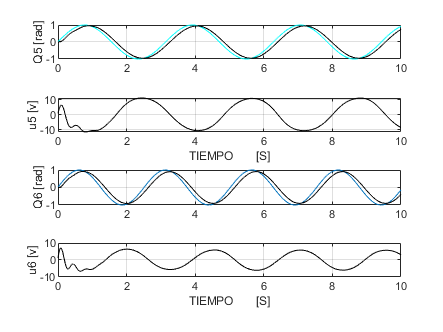


% GRAFICOS
%   ejex=linspace(0,nn*T,nn);
%   subplot(411)
%   plot(ejex,Qd1(1:nn),'red',ejex,Q1(1:nn),'k'), grid on
%   ylabel('Q1 [rad]')
%   subplot(412)
%   plot(ejex,U5(1:nn),'k'),grid on
%   xlabel('TIEMPO       [S]')
%   ylabel('u1 [v]') 
%   subplot(413)
%   plot(ejex,Qd2(1:nn),ejex,Q2(1:nn),'k'), grid on
%   ylabel('Q2 [rad]')
%   subplot(414)
%   plot(ejex,U2(1:nn),'k'), grid on
%   xlabel('TIEMPO       [S]')
%   ylabel('u2 [v]')
%   print -f -deps bscmrer
% 
%   figure
%   subplot(411)
%   plot(ejex,Qd3(1:nn),'blue',ejex,Q3(1:nn),'k'), grid on
%   ylabel('Q3 [rad]')
%   subplot(412)
%   plot(ejex,U3(1:nn),'k'),grid on
%   xlabel('TIEMPO       [S]')
%   ylabel('u3 [v]') 
%   
%   subplot(413)
%   plot(ejex,Qd4(1:nn),'magenta',ejex,Q4(1:nn),'k'), grid on
%   ylabel('Q4 [rad]')
%   subplot(414)
%   plot(ejex,U4(1:nn),'k'), grid on
%   xlabel('TIEMPO       [S]')
%   ylabel('u4 [v]')
%   print -f -deps bscmrer
% 

  figure
  subplot(411)
  plot(ejex,Qd5(1:nn),'cyan',ejex,Q5(1:nn),'k'), grid on
  ylabel('Q5 [rad]')
  subplot(412)
  plot(ejex,U5(1:nn),'k'),grid on
  xlabel('TIEMPO       [S]')
  ylabel('u5 [v]') 
  
  subplot(413)
  plot(ejex,Qd6(1:nn),ejex,Q6(1:nn), 'k'), grid on
  ylabel('Q6 [rad]')
  subplot(414)
  plot(ejex,U6(1:nn),'k'), grid on
  xlabel('TIEMPO       [S]')
  ylabel('u6 [v]')